# COVID-19 spread

## Data

breakdown = false;
if breakdown
    regione="Abruzzo";
    data_location = urlwrite("https://raw.githubusercontent.com/pcm-dpc/COVID-19/master/dati-regioni/dpc-covid19-ita-regioni.csv","./dati.csv") ;
else
    data_location = urlwrite("https://raw.githubusercontent.com/pcm-dpc/COVID-19/master/dati-andamento-nazionale/dpc-covid19-ita-andamento-nazionale.csv","./dati.csv") ;
end


dati=readtable(data_location);
delete dati.csv

if breakdown
    dati = dati(dati.denominazione_regione==regione, :);
end
dati = dati(:,{'data','totale_casi'});
dati.data = datetime(dati.data,"Format","uuuu-MM-dd'T'HH:mm:ss");
confirmed_cases = dati.totale_casi;



%START=6;
%CURRENT=START+length(confirmed_cases)-1;
%tbl=table(day,confirmed_cases);
%tbl.Properties.VariableNames{1}='Giorno';
%tbl.Properties.VariableNames{2}='Casi confermati';

disp(dati)

           data            totale_casi
    ___________________    ___________

    2020-02-24T18:00:00         229   
    2020-02-25T18:00:00         322   
    2020-02-26T18:00:00         400   
    2020-02-27T18:00:00         650   
    2020-02-28T18:00:00         888   
    2020-02-29T18:00:00        1128   
    2020-03-01T18:00:00        1694   
    2020-03-02T18:00:00        2036   
    2020-03-03T18:00:00        2502   
    2020-03-04T18:00:00        3089   
    2020-03-05T18:00:00        3858   
    2020-03-06T18:00:00        4636   
    2020-03-07T18:00:00        5883   
    2020-03-08T18:00:00        7375   
    2020-03-09T18:00:00        9172   
    2020-03-10T18:00:00       10149   
    2020-03-11T17:00:00       12462   
    2020-03-12T17:00:00       15113   
    2020-03-13T17:00:00       17660   
    2020-03-14T17:00:00       21157   
    2020-03-15T17:00:00       24747   
    2020-03-16T17:00:00       2798

day_num = datenum(dati.data - dati.data(1));
CURRENT = day_num(end);

## Data fitting

[linfit, lin_r] = fit(day_num, confirmed_cases, 'poly1');
[expfit, exp_r] = fit(day_num, confirmed_cases, 'exp1');
[logfit, log_r] = logisticFit(day_num, confirmed_cases);

## Plotting

### Linear fitting

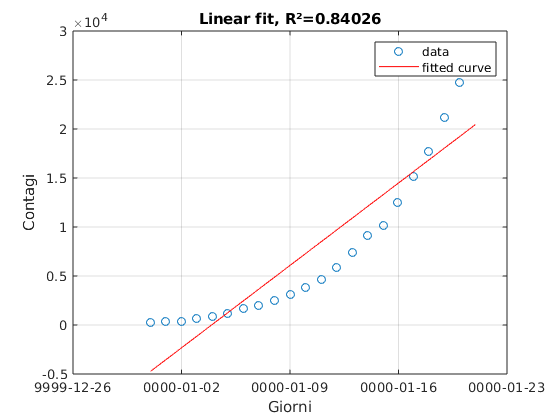

plot(linfit, day_num, confirmed_cases, "o")
datetick('x', 'yyyy-mm-dd')

grid on

title("Linear fit, R²="+lin_r.rsquare)
ylabel("Contagi")
xlabel("Giorni")


disp(linfit.p1+" nuovi contagi ogni giorno")

1201.3761 nuovi contagi ogni giorno


disp("Predicted new cases for tomorrow: "+round(linfit(CURRENT+1)-confirmed_cases(end)))

Predicted new cases for tomorrow: -6331


### Exponential fitting

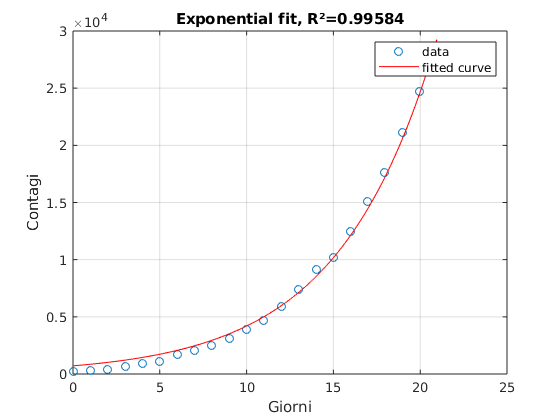

plot(expfit, day_num, confirmed_cases, "o")
grid on

title("Exponential fit, R²="+exp_r.rsquare)
ylabel("Contagi")
xlabel("Giorni")


disp("+"+expfit.b*100+"% nuovi contagi ogni giorno")

+17.713% nuovi contagi ogni giorno


disp("Predicted new cases for tomorrow: "+round(expfit(CURRENT+1)-confirmed_cases(end)))

Predicted new cases for tomorrow: 6928


## Logistic fitting

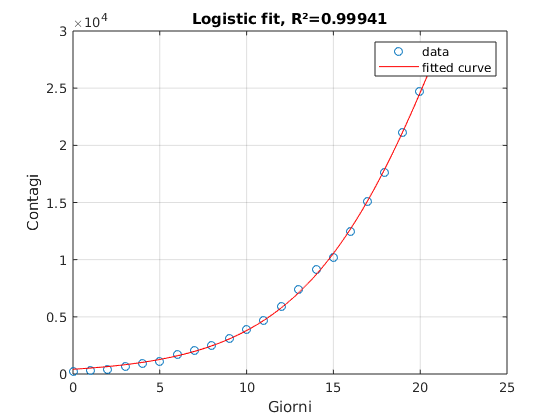

plot(logfit, day_num, confirmed_cases, "o")
grid on

title("Logistic fit, R²="+log_r.rsquare)
ylabel("Contagi")
xlabel("Giorni")


disp("Predicted new cases for tomorrow: "+round(logfit(CURRENT+1)-confirmed_cases(end)))

Predicted new cases for tomorrow: 3880


## Future projections

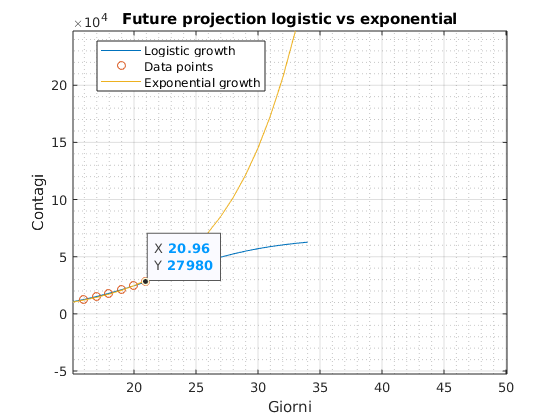

look_ahead_days = 14;
compare=true;

plot(0:(CURRENT+look_ahead_days),logfit(0:(CURRENT+look_ahead_days)))
hold on

grid on
grid minor
title("Future projection assuming logistic behaviour")
ylabel("Contagi")
xlabel("Giorni")
scatter(day_num,confirmed_cases)

legend({'Logistic growth','Data points'}, "Location","best");

if compare
    plot(0:(CURRENT+look_ahead_days),expfit(0:(CURRENT+look_ahead_days)))
    title("Future projection logistic vs exponential")
    legend({'Logistic growth','Data points', 'Exponential growth'}, "Location","best");
end

hold off

## Confronto col passato:

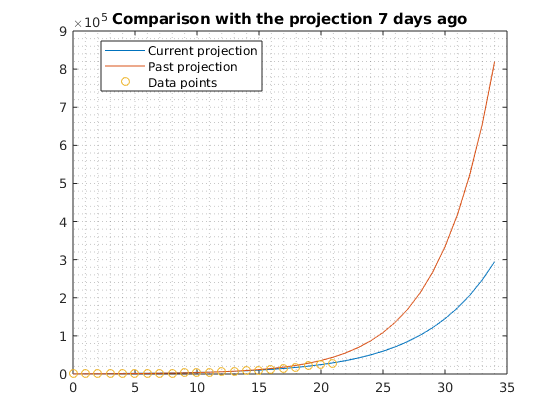

look_ahead_days = 14;
look_behind_days = 7;

model="Exponential";
if model == "Logistic"
    model_current = logfit;
    model_past = logisticFit(day_num(1:(end-look_behind_days)), confirmed_cases(1:(end-look_behind_days)));
else
    model_current = expfit;
    model_past = fit(day_num(1:(end-look_behind_days)), confirmed_cases(1:(end-look_behind_days)), 'exp1');
end


plot(0:(CURRENT+look_ahead_days),model_current(0:(CURRENT+look_ahead_days)))
grid minor
hold on
plot(0:(CURRENT+look_ahead_days),model_past(0:(CURRENT+look_ahead_days)))
scatter(day_num, confirmed_cases)
title("Comparison with the projection "+look_behind_days+" days ago");
legend({'Current projection','Past projection','Data points'}, "Location","best");
hold off

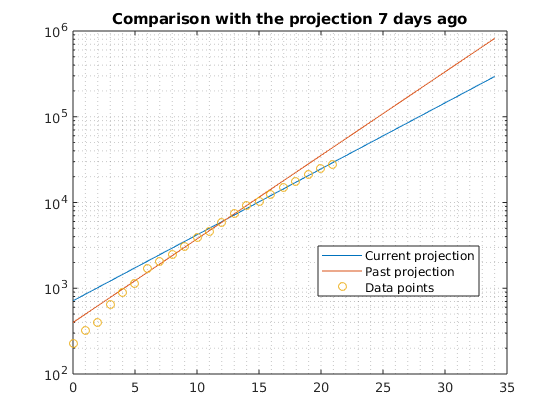


semilogy(0:(CURRENT+look_ahead_days),model_current(0:(CURRENT+look_ahead_days)))
grid minor
hold on
semilogy(0:(CURRENT+look_ahead_days),model_past(0:(CURRENT+look_ahead_days)))
scatter(day_num, confirmed_cases)
title("Comparison with the projection "+look_behind_days+" days ago");
legend({'Current projection','Past projection','Data points'}, "Location","best");
hold off